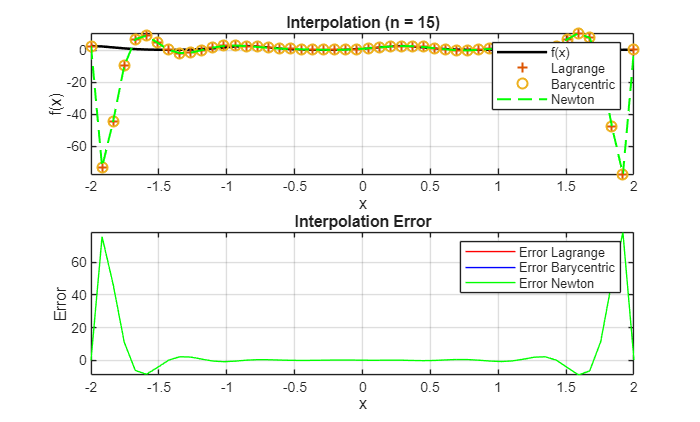

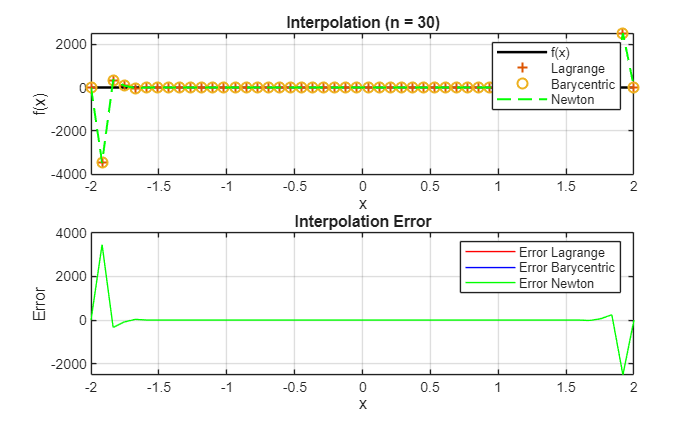

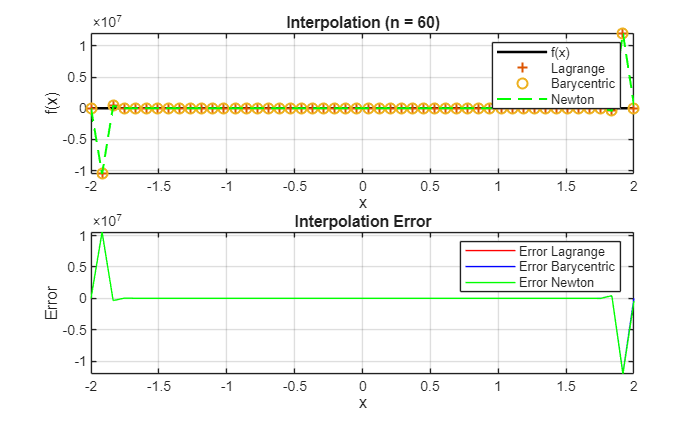

clc; clear; close all;

f = @(x) exp(sin(5.5*x));
n_values = [15, 30, 60];
x_plot = linspace(-2, 2, 50);
f_plot = f(x_plot);

for n = n_values
    x = linspace(-2, 2, n);
    f_x = f(x);

    % Evaluate using different interpolation methods
    v_poly = polyinterp(x, f_x, x_plot);
    v_bary = barycent(x, f_x, x_plot);
    v_newt = newton(x, f_x, x_plot);

    % Error
    err_poly = f_plot - v_poly;
    err_bary = f_plot - v_bary;
    err_newt = f_plot - v_newt;

    % Plot results
    figure;
    subplot(2,1,1);
    plot(x_plot, f_plot, 'k', 'LineWidth', 1.5); hold on;
    plot(x_plot, v_poly, '+', 'LineWidth', 1.2);
    plot(x_plot, v_bary, 'o', 'LineWidth', 1.2);
    plot(x_plot, v_newt, 'g--', 'LineWidth', 1.2);
    legend('f(x)', 'Lagrange', 'Barycentric', 'Newton');
    title(['Interpolation (n = ', num2str(n), ')']);
    xlabel('x'); ylabel('f(x)');
    grid on;

    subplot(2,1,2);
    plot(x_plot, err_poly, 'r', x_plot, err_bary, 'b', x_plot, err_newt, 'g');
    legend('Error Lagrange', 'Error Barycentric', 'Error Newton');
    title('Interpolation Error');
    xlabel('x'); ylabel('Error');
    grid on;
end

function v = polyinterp(x, f, u)
    n = length(x);
    m = length(u);
    v = zeros(size(u));

    for k = 1:m
        s = 0;
        for j = 1:n
            p = 1;
            for i = [1:j-1, j+1:n]
                p = p * (u(k) - x(i)) / (x(j) - x(i));
            end
            s = s + f(j) * p;
        end
        v(k) = s;
    end
end
function v = barycent(x, f, u)
    n = length(x);
    w = zeros(size(x));

    % Compute barycentric weights
    for j = 1:n
        w(j) = 1 / prod(x(j) - x([1:j-1, j+1:n]));
    end

    % Evaluate interpolation
    v = zeros(size(u));
    for k = 1:length(u)
        if any(abs(u(k) - x) < 1e-14)
            v(k) = f(abs(u(k) - x) < 1e-14);
        else
            num = sum((w .* f) ./ (u(k) - x));
            den = sum(w ./ (u(k) - x));
            v(k) = num / den;
        end
    end
end
function v = newton(x, f, u)
    n = length(x);
    a = f(:); % column vector of y-values (f(x))

    % --- Compute divided differences ---
    for j = 2:n
        for i = n:-1:j
            a(i) = (a(i) - a(i-1)) / (x(i) - x(i-j+1));
        end
    end

    % --- Evaluate Newton polynomial at points u ---
    v = zeros(size(u));
    for k = 1:length(u)
        p = a(n);
        for j = n-1:-1:1
            p = a(j) + (u(k) - x(j)) * p;
        end
        v(k) = p;
    end
end

